% Cowan-style neural network with Linear Rectified Transfer function 
javaaddpath('D:/Transfer_Entropy/infodynamics-dist-1.5/infodynamics.jar');
addpath('D:/Transfer_Entropy/infodynamics-dist-1.5\demos\octave');
SampleTime = 1000; % unit s 
dt = 0.01; % unit s, simulation rate at 100 Hz
t = 0:dt:SampleTime;
length_t = length(t);

sampling_index = 500:20:length_t; % sampling at 5 Hz

% linear rectified function
threshold_theta = 0;
b = -threshold_theta; % b passes into the updating function as a postive term
transfer_func_linear = @(x) max(0, x);
transfer_func_quadratic = @(x) max(0, x)^2;

- **The bistable case (Symmetric weights, expecting symmetric TE)**

% Set the connection weight matrix
c = 0.01; 
k = 0.01;
W = [1 -0.5;
     -0.5 1]; 
threshold_theta = 0; % threshold at 0, network will update if firing rate not at zero
b = -threshold_theta; 

sim_num = 30;
te_result_ytox_Gaussian= zeros(1,sim_num);
te_result_xtoy_Gaussian = zeros(1, sim_num); 
te_result_ytox_KSG= zeros(1,sim_num);
te_result_xtoy_KSG = zeros(1, sim_num); 
te_result_ytox_Kernel= zeros(1,sim_num);
te_result_xtoy_Kernel = zeros(1, sim_num); 

for i = 1:sim_num
    initial_condition = normrnd(0.5,1,2,1);
    [r{i},~,~,~] = sim_network(W, c, k, b, transfer_func_linear, SampleTime, dt, initial_condition); 
    temp = r{i};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    te_result_ytox_Gaussian(i) = transfer_entropy_main(X,Y,2,2,1, "Gaussian");
    te_result_xtoy_Gaussian(i) = transfer_entropy_main(Y,X,2,2,1, "Gaussian");
    te_result_ytox_KSG(i) = transfer_entropy_main(X,Y,2,2,1, "KSG");
    te_result_xtoy_KSG(i) = transfer_entropy_main(Y,X,2,2,1, "KSG");
    te_result_ytox_Kernel(i) = transfer_entropy_main(X,Y,2,2,1, "Kernel");
    te_result_xtoy_Kernel(i) = transfer_entropy_main(Y,X,2,2,1, "Kernel");
end 


% Compare the results from various estimators
table([mean(te_result_xtoy_Gaussian); mean(te_result_xtoy_KSG); mean(te_result_xtoy_Kernel)], ...
        [mean(te_result_ytox_Gaussian); mean(te_result_ytox_KSG); mean(te_result_ytox_Kernel)], ...
        'RowNames',{'Gaussian','KSG', 'Kernel'}, ...
        'VariableNames', {'X_to_Y','Y_to_X'})

ans = 3×2 table
                 X_to_Y       Y_to_X 
                _________    ________

    Gaussian     0.013299     0.01241
    KSG         0.0097913    0.010976
    Kernel       0.032534    0.031129


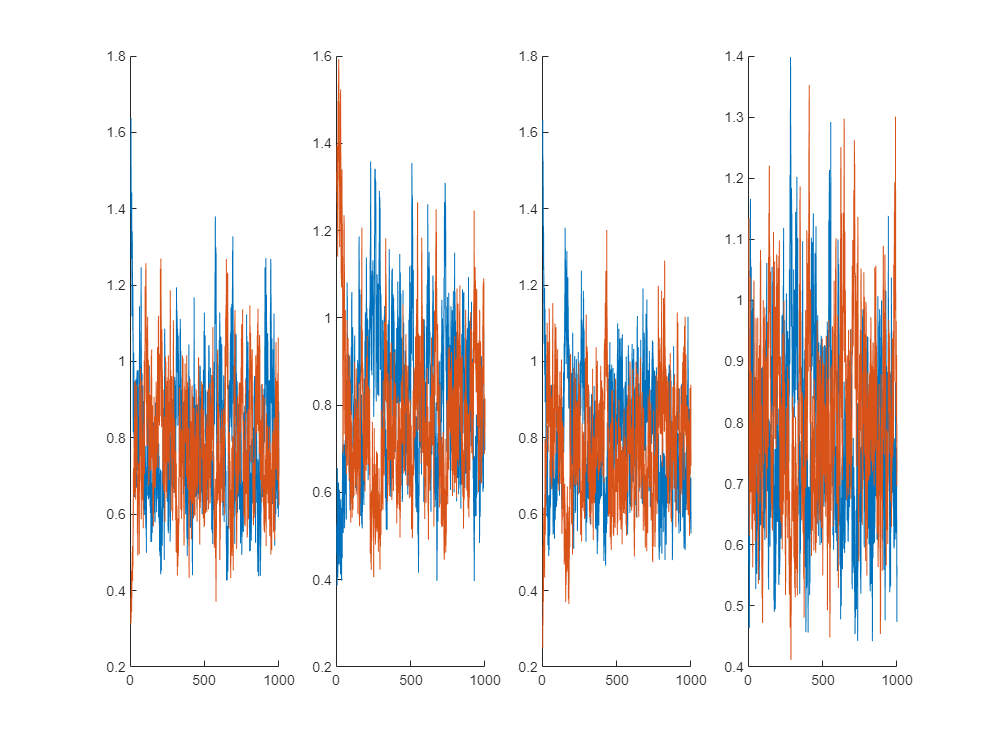

% Plot some runs ofstate trajectories
figure('Renderer', 'painters', 'Position', [10 10 900 600])
for i = 1:4
subplot(1,4,i)
hold on 
temp = r{i};
X = temp(1,sampling_index)';
Y = temp(2,sampling_index)';
plot(t(sampling_index), X)
plot(t(sampling_index), Y)
hold off 
end 

% Save the data
save('Testing_Two_Node_Network/bistable.mat','r')

**2. Asymmetric Inhibition**

sim_num = 50;
te_result_ytox_Gaussian= zeros(1,sim_num);
te_result_xtoy_Gaussian = zeros(1, sim_num); 
te_result_ytox_KSG= zeros(1,sim_num);
te_result_xtoy_KSG = zeros(1, sim_num); 
te_result_ytox_Kernel= zeros(1,sim_num);
te_result_xtoy_Kernel = zeros(1, sim_num); 

c = 0.5; 
k = 0.5;
W = [1 -0.5;
    0 1];
b = 0;
for i = 1:sim_num
    initial_condition = normrnd(0.5,1,2,1);
    [r{i},~,~,~] = sim_network(W, c, k, b, transfer_func_linear, SampleTime, dt, initial_condition); 
    temp = r{i};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    te_result_ytox_Gaussian(i) = transfer_entropy_main(X,Y,1,1,1, "Gaussian");
    te_result_xtoy_Gaussian(i) = transfer_entropy_main(Y,X,1,1,1, "Gaussian");
    te_result_ytox_KSG(i) = transfer_entropy_main(X,Y,1,1,1, "KSG");
    te_result_xtoy_KSG(i) = transfer_entropy_main(Y,X,1,1,1, "KSG");
    te_result_ytox_Kernel(i) = transfer_entropy_main(X,Y,2,2,1, "Kernel");
    te_result_xtoy_Kernel(i) = transfer_entropy_main(Y,X,2,2,1, "Kernel");
    
end 
table([mean(te_result_xtoy_Gaussian); mean(te_result_xtoy_KSG); mean(te_result_xtoy_Kernel)], ...
        [mean(te_result_ytox_Gaussian); mean(te_result_ytox_KSG); mean(te_result_ytox_Kernel)], ...
        'RowNames',{'Gaussian','KSG', 'Kernel'}, ...
        'VariableNames', {'X_to_Y','Y_to_X'}) 

ans = 3×2 table
                  X_to_Y       Y_to_X 
                __________    ________

    Gaussian    0.00017049    0.012743
    KSG         -0.0010668    0.039614
    Kernel       0.0026031    0.051447


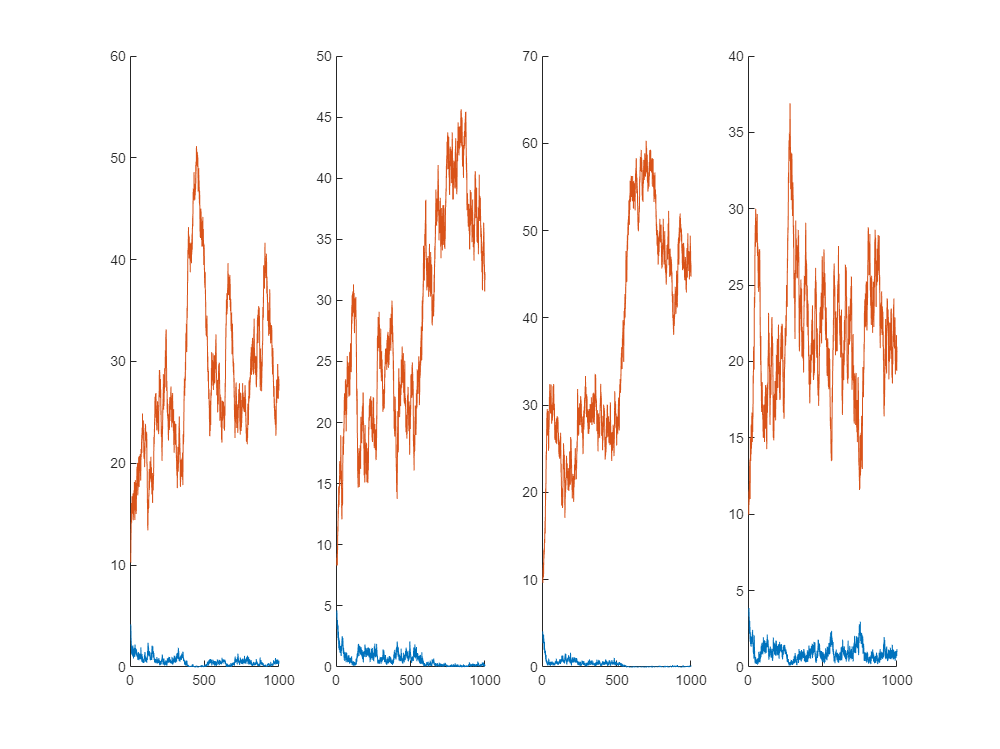

% Plot
figure('Renderer', 'painters', 'Position', [10 10 900 600])
for i = 1:4
subplot(1,4,i)
hold on 
temp = r{i};
X = temp(1,sampling_index)';
Y = temp(2,sampling_index)';
plot(t(sampling_index), X)
plot(t(sampling_index), Y)
hold off 
end 

% Save the data
save('Testing_Two_Node_Network/asymmetric_inhibition.mat','r')

    **2.1 Asymmetric Excitatory**

**KSG does not work when network explodes (each state sparsely sampled)**

clear r 
sim_num = 50;
te_result_ytox_Gaussian= zeros(1,sim_num);
te_result_xtoy_Gaussian = zeros(1, sim_num); 
te_result_ytox_KSG= zeros(1,sim_num);
te_result_xtoy_KSG = zeros(1, sim_num); 
te_result_ytox_Kernel= zeros(1,sim_num);
te_result_xtoy_Kernel = zeros(1, sim_num); 

c = 0.1; 
k = 0.1;
W = [1 0.5;
    0 1];
b = 0;
for i = 1:sim_num
    initial_condition = normrnd(0.5,1,2,1);
    [r{i},~,~,~] = sim_network(W, c, k, b, transfer_func_linear, SampleTime, dt, initial_condition); 
    temp = r{i};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    te_result_ytox_Gaussian(i) = transfer_entropy_main(X,Y,1,1,1, "Gaussian");
    te_result_xtoy_Gaussian(i) = transfer_entropy_main(Y,X,1,1,1, "Gaussian");
    te_result_ytox_KSG(i) = transfer_entropy_main(X,Y,1,1,1, "KSG");
    te_result_xtoy_KSG(i) = transfer_entropy_main(Y,X,1,1,1, "KSG");
    te_result_ytox_Kernel(i) = transfer_entropy_main(X,Y,2,2,1, "Kernel");
    te_result_xtoy_Kernel(i) = transfer_entropy_main(Y,X,2,2,1, "Kernel");
    
end 
table([mean(te_result_xtoy_Gaussian); mean(te_result_xtoy_KSG); mean(te_result_xtoy_Kernel)], ...
        [mean(te_result_ytox_Gaussian); mean(te_result_ytox_KSG); mean(te_result_ytox_Kernel)], ...
        'RowNames',{'Gaussian','KSG', 'Kernel'}, ...
        'VariableNames', {'X_to_Y','Y_to_X'}) 

ans = 3×2 table
                 X_to_Y        Y_to_X  
                _________    __________

    Gaussian    0.0001739       0.62389
    KSG         0.0011401     -0.038645
    Kernel      0.0084528    0.00027686


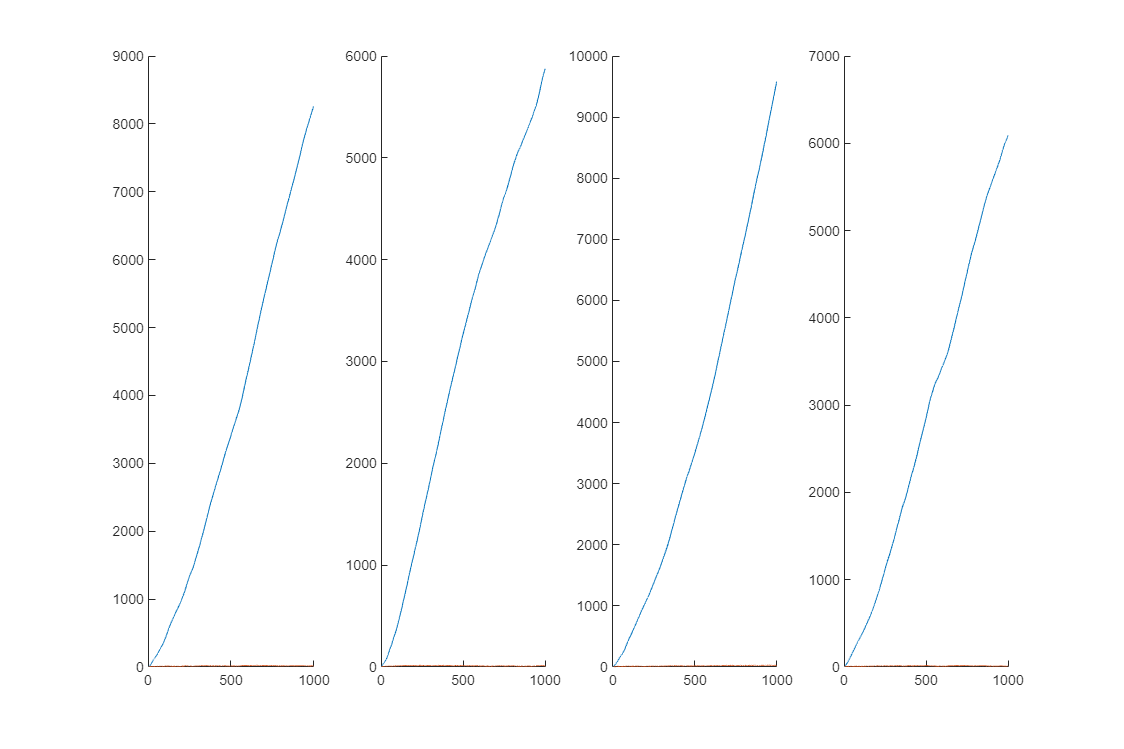

figure('Renderer', 'painters', 'Position', [10 10 900 600])
for i = 1:4
subplot(1,4,i)
hold on 
temp = r{i};
X = temp(1,sampling_index)';
Y = temp(2,sampling_index)';
plot(t(sampling_index), X)
plot(t(sampling_index), Y)
hold off 
end 

% Save the data
save('Testing_Two_Node_Network/asymmetric_excitatory.mat','r')

**3. Non-symmetric case increasing connection weights**

Range the connection from y to x from 0 to 5. Expect to see TE from y to x increase and x to y stays the same. 

sim_run = 50;
c = 0.5; 
k = 0.5;
p = 0:0.5:5;
b = 0;
te_result_ytox_Gaussian= zeros(sim_run, length(p));
te_result_xtoy_Gaussian = zeros(sim_run, length(p));
te_result_ytox_KSG= zeros(sim_run, length(p));
te_result_xtoy_KSG = zeros(sim_run, length(p));
te_result_ytox_Kernel= zeros(sim_run, length(p));
te_result_xtoy_Kernel = zeros(sim_run, length(p));
for j = 1:sim_run
    for i = 1:length(p)
        W = [0 -p(i);
             0 0];
        initial_condition = normrnd(5,1,2,1);
        [r{i,j},~,~,~] = sim_network(W, c, k, b, transfer_func_linear, SampleTime, dt,initial_condition);
        temp = r{i,j};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    te_result_ytox_Gaussian(j,i) = transfer_entropy_main(X,Y,1,1,1, "Gaussian");
    te_result_xtoy_Gaussian(j,i) = transfer_entropy_main(Y,X,1,1,1, "Gaussian");
    te_result_ytox_KSG(j,i) = transfer_entropy_main(X,Y,1,1,1, "KSG");
    te_result_xtoy_KSG(j,i) = transfer_entropy_main(Y,X,1,1,1, "KSG");
    te_result_ytox_Kernel(j,i) = transfer_entropy_main(X,Y,2,2,1, "Kernel");
    te_result_xtoy_Kernel(j,i) = transfer_entropy_main(Y,X,2,2,1, "Kernel");
    end
end
% Save the data
save('Testing_Two_Node_Network/increasing_connections.mat','r')

Error bar indicates one standard error

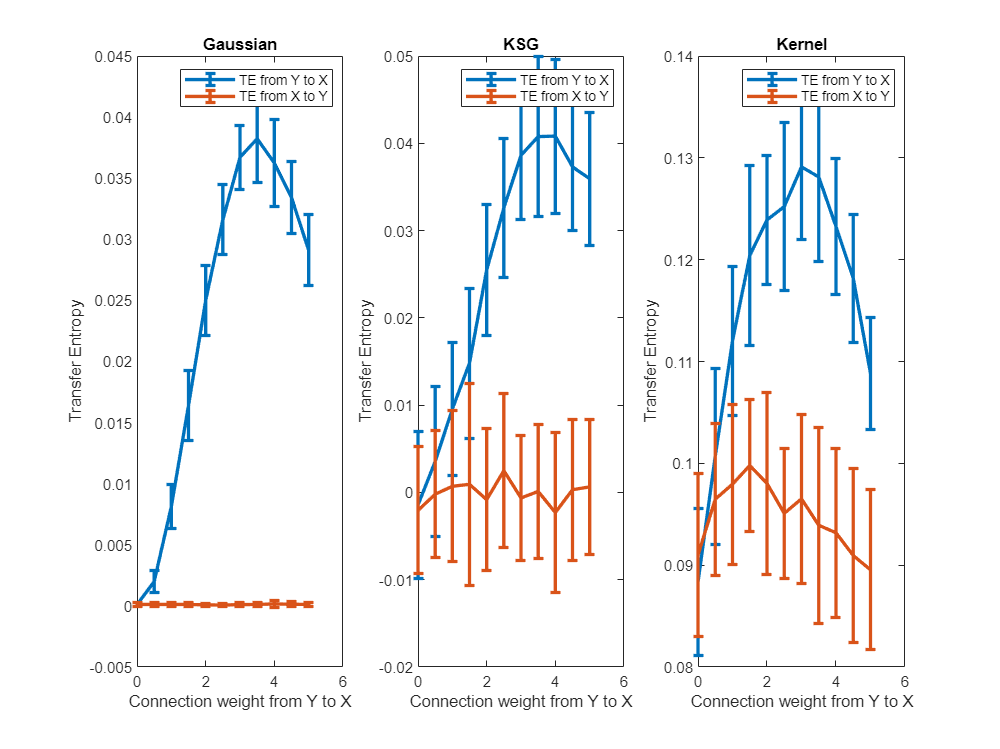

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(1,3,1)
errorbar(p, mean(te_result_ytox_Gaussian,1), sqrt(var(te_result_ytox_Gaussian,1)), 'LineWidth',2)
hold on 
errorbar(p, mean(te_result_xtoy_Gaussian,1), sqrt(var(te_result_xtoy_Gaussian,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Connection weight from Y to X")
ylabel("Transfer Entropy")
title("Gaussian")
hold off
subplot(1,3,2)
errorbar(p, mean(te_result_ytox_KSG,1), sqrt(var(te_result_ytox_KSG,1)), 'LineWidth',2)
hold on 
errorbar(p, mean(te_result_xtoy_KSG,1), sqrt(var(te_result_xtoy_KSG,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Connection weight from Y to X")
ylabel("Transfer Entropy")
title("KSG")
hold off
subplot(1,3,3)
errorbar(p, mean(te_result_ytox_Kernel,1), sqrt(var(te_result_ytox_Kernel,1)), 'LineWidth',2)
hold on 
errorbar(p, mean(te_result_xtoy_Kernel,1), sqrt(var(te_result_xtoy_Kernel,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Connection weight from Y to X")
ylabel("Transfer Entropy")
title("Kernel")
hold off

Plot one run for each connection weight

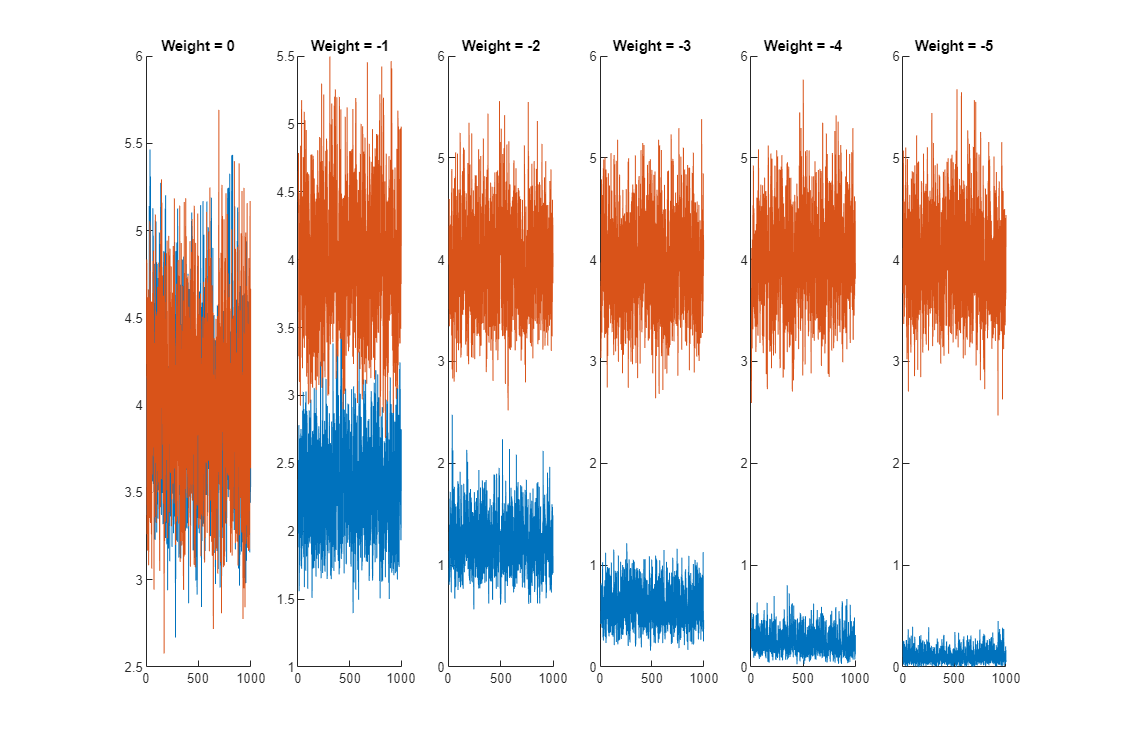

figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot_index = 1:2:length(p);
for i = 1:length(plot_index)
    subplot(1,length(plot_index), i)
    hold on 
    temp = r{plot_index(i),1};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    plot(t(sampling_index), X)
    plot(t(sampling_index), Y)
    hold off 
    title("Weight = " + string(-p(plot_index(i))))
end 

**4. Nonsymmetric, ranging common drive**

clear r g p s  
sim_run = 50;
c = 0:0.2:2; 
k = 0.5;
p = -0.5;

p = -0.5000

b = 0;
W = [0 p;
     0 0];
te_result_ytox_Gaussian= zeros(sim_run, length(c));
te_result_xtoy_Gaussian = zeros(sim_run, length(c));
te_result_ytox_KSG= zeros(sim_run, length(c));
te_result_xtoy_KSG = zeros(sim_run, length(c));
te_result_ytox_Kernel= zeros(sim_run, length(c));
te_result_xtoy_Kernel = zeros(sim_run, length(c));
for j = 1:sim_run
    for i = 1:length(c)
        i
        initial_condition = normrnd(5,1,2,1);
        [r{i,j},~,~,~] = sim_network(W, c(i), k, b, transfer_func_linear, SampleTime, dt,initial_condition);
        temp = r{i,j};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    te_result_ytox_Gaussian(j,i) = transfer_entropy_main(X,Y,1,1,1, "Gaussian");
    te_result_xtoy_Gaussian(j,i) = transfer_entropy_main(Y,X,1,1,1, "Gaussian");
    te_result_ytox_KSG(j,i) = transfer_entropy_main(X,Y,1,1,1, "KSG");
    te_result_xtoy_KSG(j,i) = transfer_entropy_main(Y,X,1,1,1, "KSG");
    te_result_ytox_Kernel(j,i) = transfer_entropy_main(X,Y,2,2,1, "Kernel");
    te_result_xtoy_Kernel(j,i) = transfer_entropy_main(Y,X,2,2,1, "Kernel");
    end
end
% Save the data

save('Testing_Two_Node_Network/increasing_private_noise.mat','r', 'te_result_ytox_Gaussian', 'te_result_xtoy_Gaussian', ...
    'te_result_ytox_KSG', 'te_result_xtoy_KSG', 'te_result_ytox_Kernel', 'te_result_xtoy_Kernel')

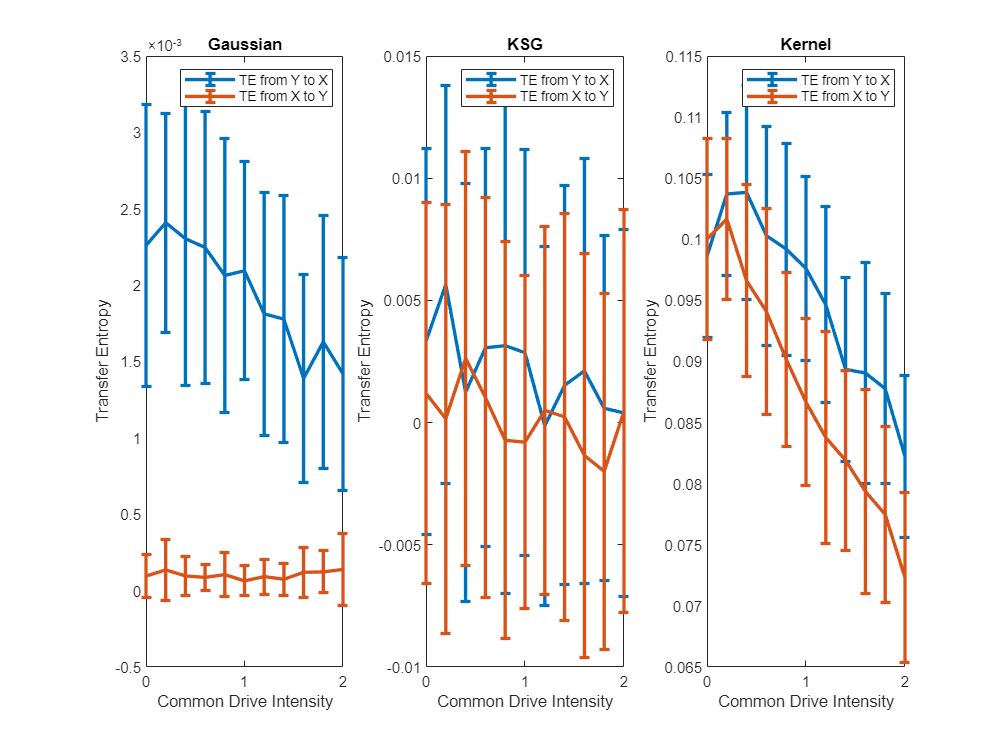

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(1,3,1)
errorbar(c, mean(te_result_ytox_Gaussian,1), sqrt(var(te_result_ytox_Gaussian,1)), 'LineWidth',2)
hold on 
errorbar(c, mean(te_result_xtoy_Gaussian,1), sqrt(var(te_result_xtoy_Gaussian,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Common Drive Intensity")
ylabel("Transfer Entropy")
title("Gaussian")
hold off
subplot(1,3,2)
errorbar(c, mean(te_result_ytox_KSG,1), sqrt(var(te_result_ytox_KSG,1)), 'LineWidth',2)
hold on 
errorbar(c, mean(te_result_xtoy_KSG,1), sqrt(var(te_result_xtoy_KSG,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Common Drive Intensity")
ylabel("Transfer Entropy")
title("KSG")
hold off
subplot(1,3,3)
errorbar(c, mean(te_result_ytox_Kernel,1), sqrt(var(te_result_ytox_Kernel,1)), 'LineWidth',2)
hold on 
errorbar(c, mean(te_result_xtoy_Kernel,1), sqrt(var(te_result_xtoy_Kernel,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Common Drive Intensity")
ylabel("Transfer Entropy")
title("Kernel")
hold off

Plot one run for each connection weight

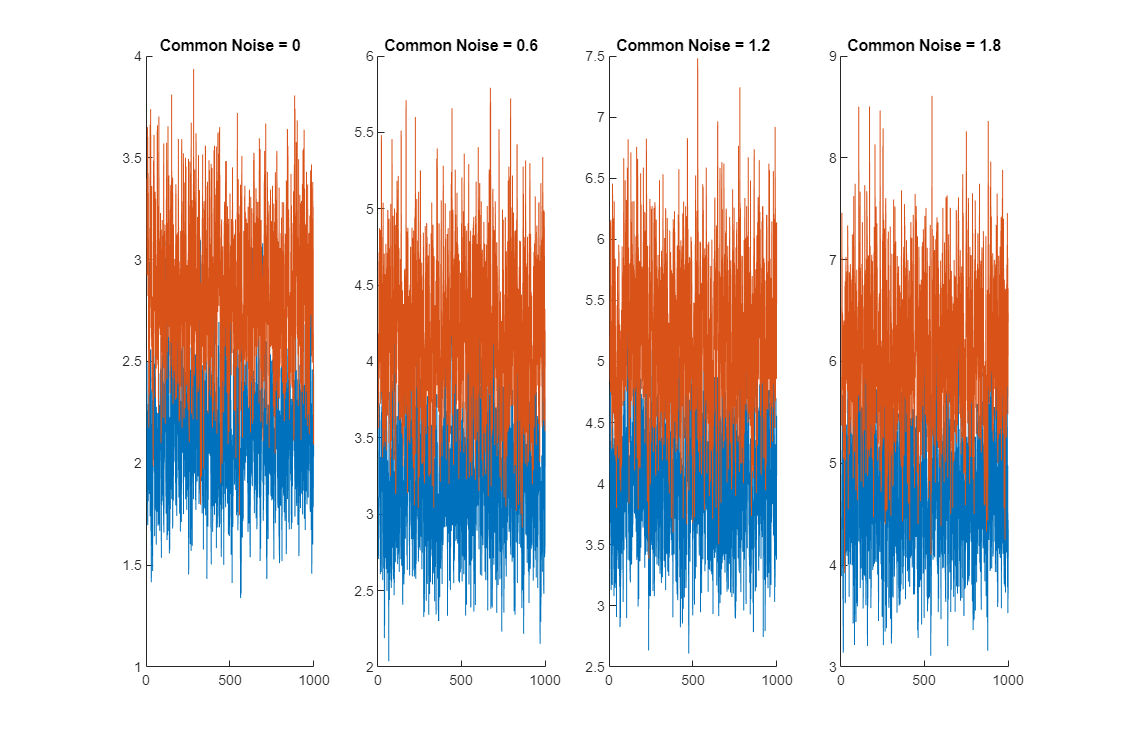

figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot_index = 1:3:length(c);
for i = 1:length(plot_index)
    subplot(1,length(plot_index), i)
    hold on 
    temp = r{plot_index(i),1};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    plot(t(sampling_index), X)
    plot(t(sampling_index), Y)
    hold off 
    title("Common Noise = " + string(c(plot_index(i))))
end 

**5. Nonsymmetric, ranging private drive**

clear r g p s  
sim_run = 50;
c = 0.5; 
k = 0:0.2:2;
p = -0.5;
b = 0;
W = [0 p;
     0 0];
te_result_ytox_Gaussian= zeros(sim_run, length(k));
te_result_xtoy_Gaussian = zeros(sim_run, length(k));
te_result_ytox_KSG= zeros(sim_run, length(k));
te_result_xtoy_KSG = zeros(sim_run, length(k));
te_result_ytox_Kernel= zeros(sim_run, length(k));
te_result_xtoy_Kernel = zeros(sim_run, length(k));
for j = 1:sim_run
    for i = 1:length(k)
        
        initial_condition = normrnd(5,1,2,1);
        [r{i,j},~,~,~] = sim_network(W, c, k(i), b, transfer_func_linear, SampleTime, dt,initial_condition);
        temp = r{i,j};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    te_result_ytox_Gaussian(j,i) = transfer_entropy_main(X,Y,1,1,1, "Gaussian");
    te_result_xtoy_Gaussian(j,i) = transfer_entropy_main(Y,X,1,1,1, "Gaussian");
    te_result_ytox_KSG(j,i) = transfer_entropy_main(X,Y,1,1,1, "KSG");
    te_result_xtoy_KSG(j,i) = transfer_entropy_main(Y,X,1,1,1, "KSG");
    te_result_ytox_Kernel(j,i) = transfer_entropy_main(X,Y,2,2,1, "Kernel");
    te_result_xtoy_Kernel(j,i) = transfer_entropy_main(Y,X,2,2,1, "Kernel");
    end
end
% Save the data
save('Testing_Two_Node_Network/increasing_private_noise.mat','r', 'te_result_ytox_Gaussian', 'te_result_xtoy_Gaussian', ...
    'te_result_ytox_KSG', 'te_result_xtoy_KSG', 'te_result_ytox_Kernel', 'te_result_xtoy_Kernel')

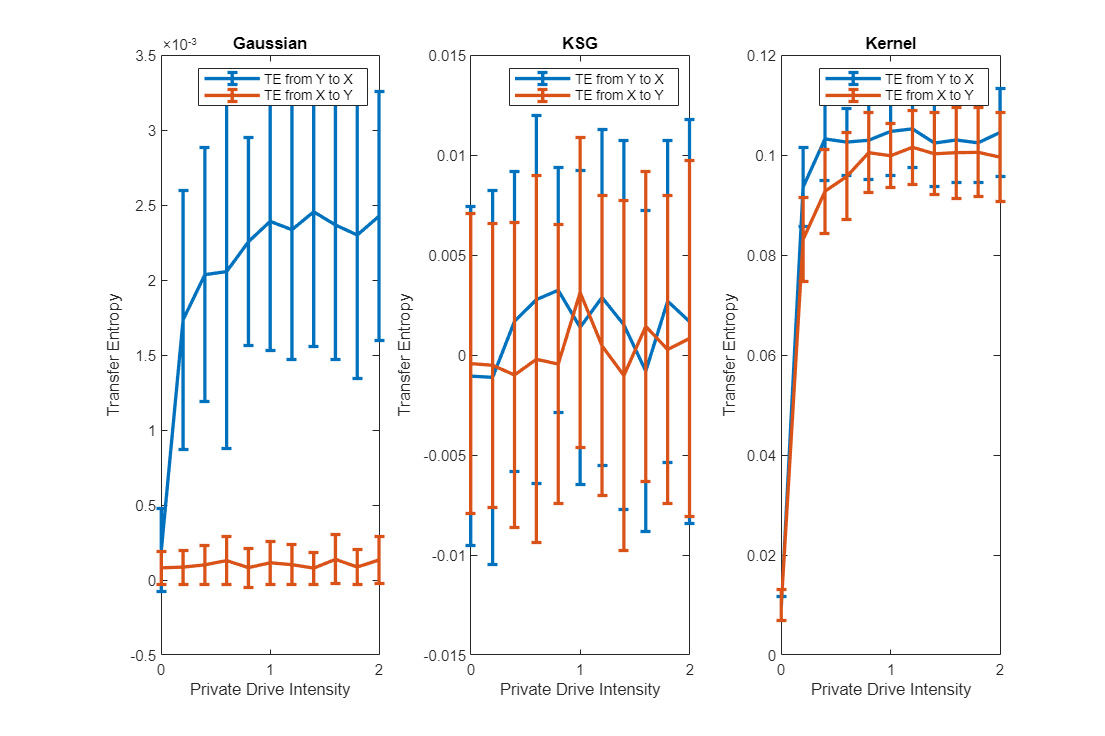

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(1,3,1)
errorbar(k, mean(te_result_ytox_Gaussian,1), sqrt(var(te_result_ytox_Gaussian,1)), 'LineWidth',2)
hold on 
errorbar(k, mean(te_result_xtoy_Gaussian,1), sqrt(var(te_result_xtoy_Gaussian,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Private Drive Intensity")
ylabel("Transfer Entropy")
title("Gaussian")
hold off
subplot(1,3,2)
errorbar(k, mean(te_result_ytox_KSG,1), sqrt(var(te_result_ytox_KSG,1)), 'LineWidth',2)
hold on 
errorbar(k, mean(te_result_xtoy_KSG,1), sqrt(var(te_result_xtoy_KSG,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Private Drive Intensity")
ylabel("Transfer Entropy")
title("KSG")
hold off
subplot(1,3,3)
errorbar(k, mean(te_result_ytox_Kernel,1), sqrt(var(te_result_ytox_Kernel,1)), 'LineWidth',2)
hold on 
errorbar(k, mean(te_result_xtoy_Kernel,1), sqrt(var(te_result_xtoy_Kernel,1)), 'LineWidth',2)
legend("TE from Y to X", "TE from X to Y")
xlabel("Private Drive Intensity")
ylabel("Transfer Entropy")
title("Kernel")
hold off

Plot one run for each connection weight

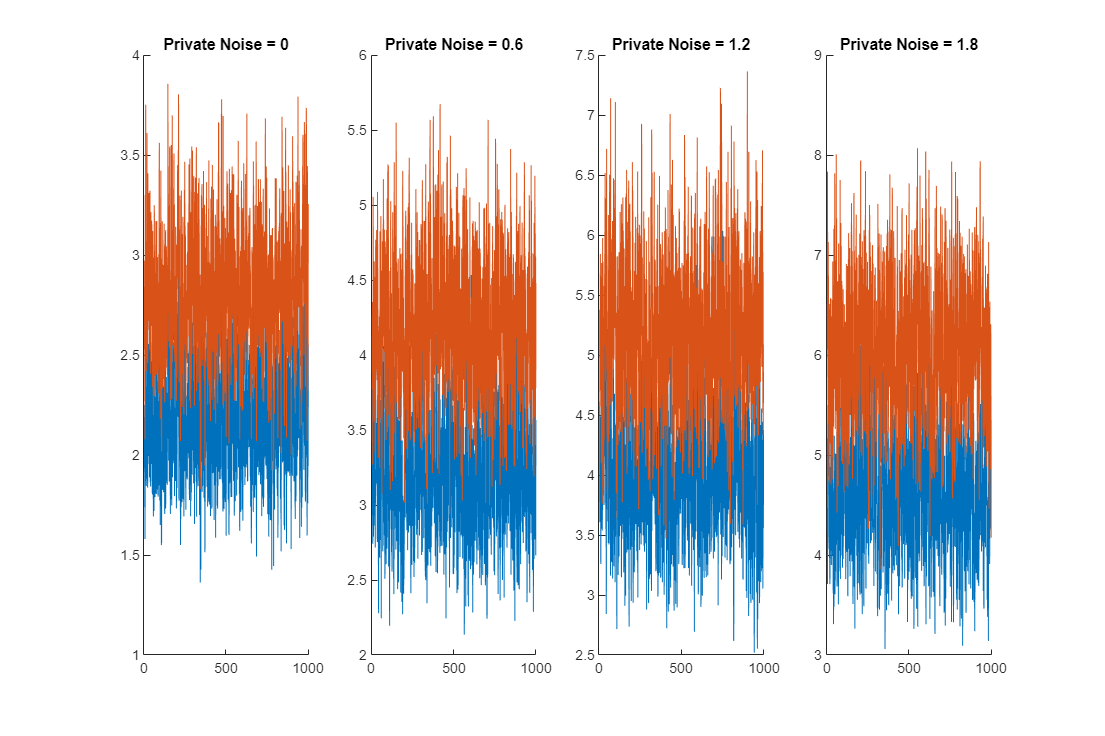

figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot_index = 1:3:length(k);
for i = 1:length(plot_index)
    subplot(1,length(plot_index), i)
    hold on 
    temp = r{plot_index(i),1};
    X = temp(1,sampling_index)';
    Y = temp(2,sampling_index)';
    plot(t(sampling_index), X)
    plot(t(sampling_index), Y)
    hold off 
    title("Private Noise = " + string(k(plot_index(i))))
end 